%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain length on DNA/RNA toehold
%exchange kinetics including spontaneous incumbent and invader dissociation

%b = 20 %define branch migration domain length
g = 2 %define invader toehold length

g = 2

g2 = 4 %define incumbent toehold length

g2 = 4


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.3*R*temp

dGrd = -0.1777

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    bg2 = b + g2 %define branch migration domain + incumbent toehold length

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp((dGbp + dGrd)/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates
    Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates
    Koff = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    %define spontaneous invader dissociation rates
    Koff_inv = [repmat(0, [1, g+1])];
    for n = b+g-1:-1:g+1
        Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g2+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    j_cycle = zeros(1,numel(Kf));
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn);
        j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
    end
        
    j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end))
    first_pass_time (b-9) = (1/j_disp)*sum(Pn_jN_1)%calculate first passage time
    %first_pass_time (b-9) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8));%calculate effective rate constant
    prob_unbound(b-9) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate prob of being in unbound state
end

bg2 = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911    2.7147         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 16

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911    2.7147    3.6915         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 17

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911    2.7147    3.6915    5.0100         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 18

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911    2.7147    3.6915    5.0100    6.7897         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 19

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time = 	1.0e+05 *

    1.9911    2.7147    3.6915    5.0100    6.7897    9.1922         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 20

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 21

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 22

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813    2.2722         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813    2.2722    3.0698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813    2.2722    3.0698    4.1465         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813    2.2722    3.0698    4.1465    5.5999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.1991    0.2715    0.3691    0.5010    0.6790    0.9192    1.2435    1.6813    2.2722    3.0698    4.1465    5.5999    7.5618         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 28

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3219    0.3219    0.3219    0.3219    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0001    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 29

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0007


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 30

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610    2.5124         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 31

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610    2.5124    3.3916         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 32

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610    2.5124    3.3916    4.5785         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0


bg2 = 33

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610    2.5124    3.3916    4.5785    6.1806         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0


bg2 = 34

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0199    0.0271    0.0369    0.0501    0.0679    0.0919    0.1244    0.1681    0.2272    0.3070    0.4147    0.5600    0.7562    1.0210    1.3785    1.8610    2.5124    3.3916    4.5785    6.1806    8.3432         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0


bg2 = 35

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0


bg2 = 36

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0


bg2 = 37

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0


bg2 = 38

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522    2.7702         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


bg2 = 39

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522    2.7702    3.7394         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0


bg2 = 40

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522    2.7702    3.7394    5.0478         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0


bg2 = 41

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522    2.7702    3.7394    5.0478    6.8138         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0


bg2 = 42

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0020    0.0027    0.0037    0.0050    0.0068    0.0092    0.0124    0.0168    0.0227    0.0307    0.0415    0.0560    0.0756    0.1021    0.1378    0.1861    0.2512    0.3392    0.4579    0.6181    0.8343    1.1262    1.5203    2.0522    2.7702    3.7394    5.0478    6.8138    9.1977         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0


bg2 = 43

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0017    0.0023    0.0031    0.0041    0.0056    0.0076    0.0102    0.0138    0.0186    0.0251    0.0339    0.0458    0.0618    0.0834    0.1126    0.1520    0.2052    0.2770    0.3739    0.5048    0.6814    0.9198    1.2416


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


bg2 = 44

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 668.1379

k_Cf = 2.4453e+04

k_DC = 901.8918

k_FE = 0

k_FF = 1

Kf =     0.0000    3.2187    3.2187    3.2187    3.2187    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245    0.0245


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Koff =          0         0         0         0         0   40.6295    2.4218    0.1444    0.0086    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0108    0.1340


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0045

first_pass_time =     0.0002    0.0003    0.0004    0.0005    0.0007    0.0009    0.0012    0.0017    0.0023    0.0031    0.0041    0.0056    0.0076    0.0102    0.0138    0.0186    0.0251    0.0339    0.0458    0.0618    0.0834    0.1126    0.1520    0.2052    0.2770    0.3739    0.5048    0.6814    0.9198    1.2416


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


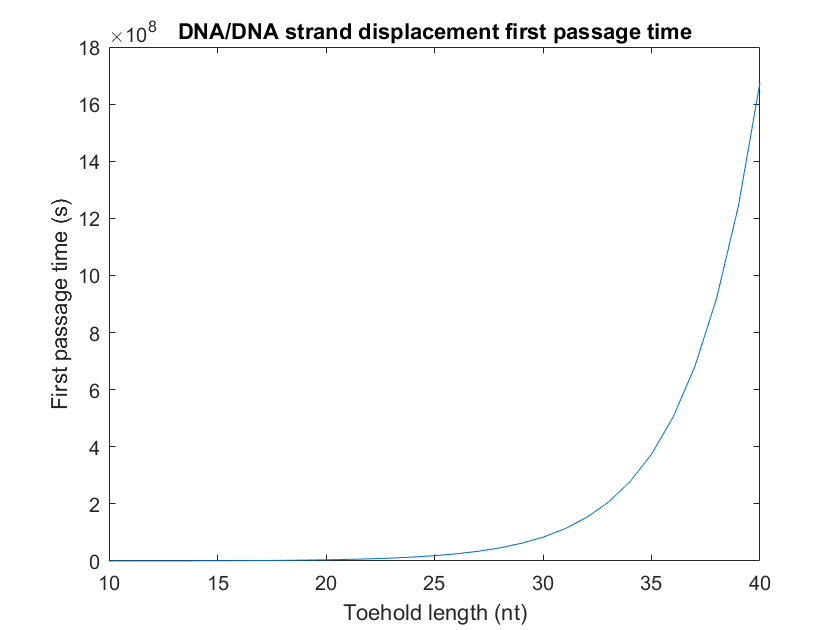

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

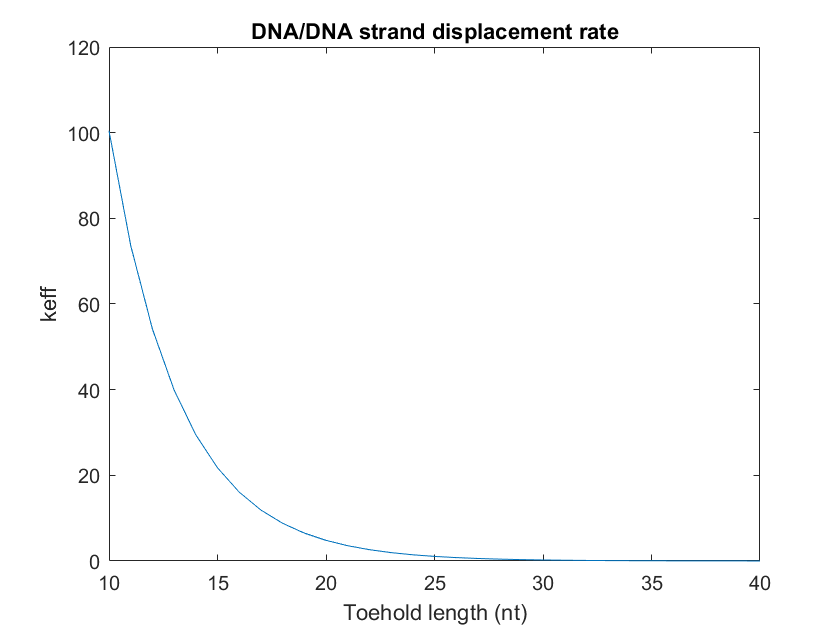


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

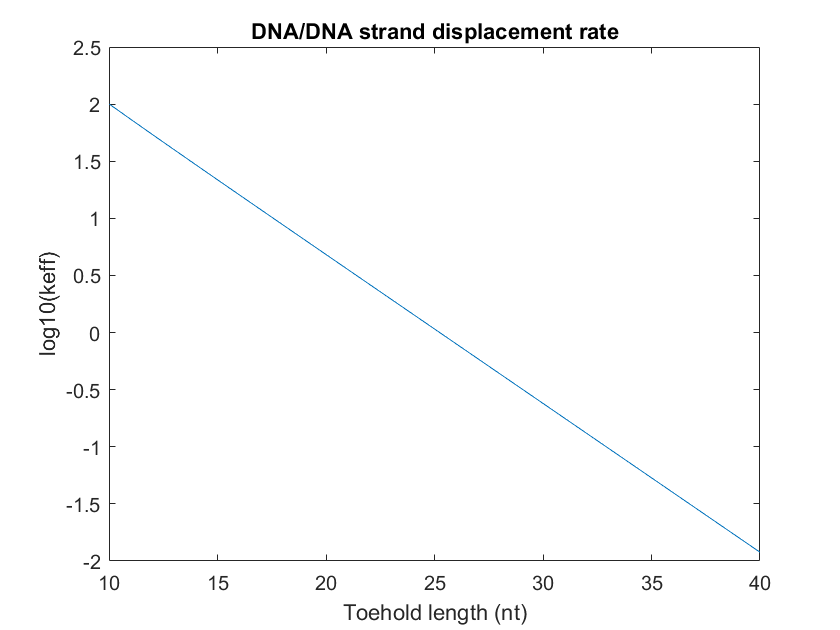


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  